# Load data to table from progress.txt

A = cell(1,6);
for i = 0:5
    filename = sprintf("Quad4_s%d/progress.txt", i);
    A{i+1} = readtable(filename);
end

% filename = 'Quad4_s0/progress.txt';
% A0 = readtable(filename)

# Plot value wrt the number of epochs

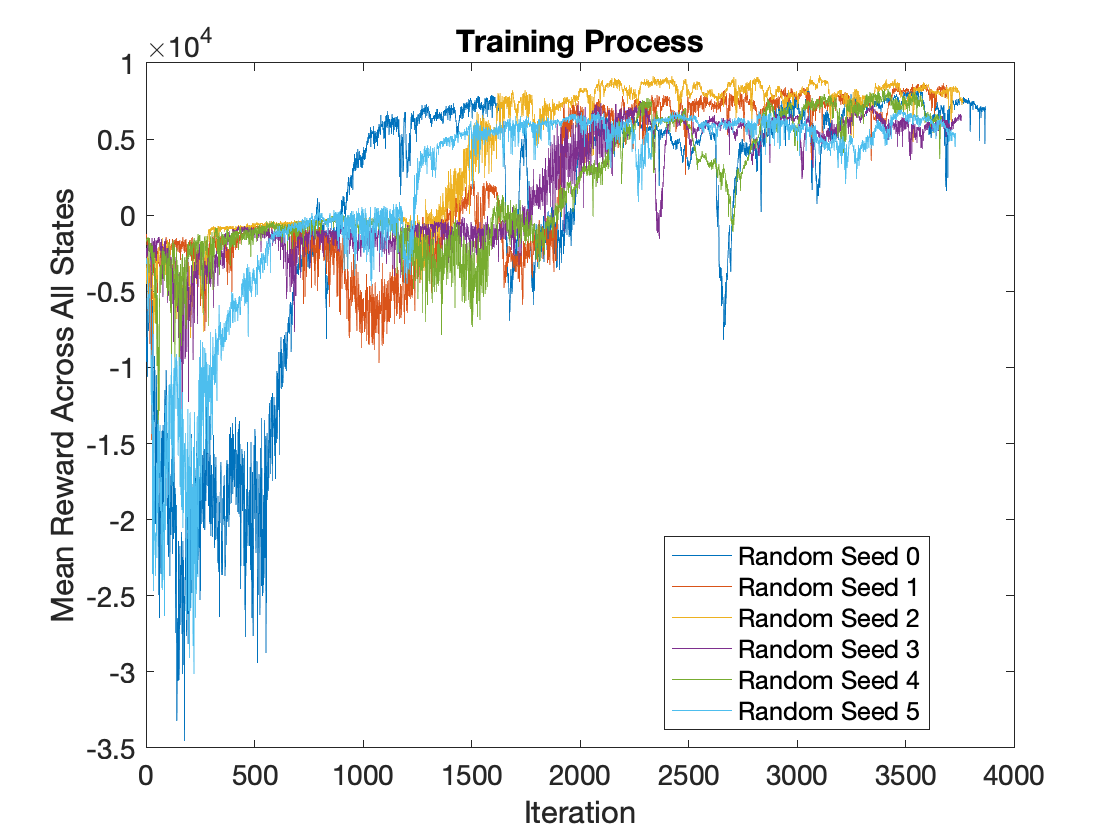

ff = figure;
for i = 1:6
    plot(A{i}.Epoch,A{i}.AverageEpRet);
    hold on
end
legend('Random Seed 0','Random Seed 1','Random Seed 2','Random Seed 3','Random Seed 4','Random Seed 5','Location','best')
title('Training Process')
xlabel('Iteration')
ylabel('Mean Reward Across All States') 
ax = gca;
ax.FontSize = 14;
% saveas(f,'Progress.pdf')
print(ff,'Progress','-dpdf','-bestfit')

# Functions

for i = 1:6
    [m,i]=max(A{i}.AverageEpRet)
end

m = 8.3468e+03

i = 3054

m = 8.6515e+03

i = 3675

m = 9.1702e+03

i = 3105

m = 7.4461e+03

i = 2280

m = 8.3094e+03

i = 3420

m = 6.9401e+03

i = 3471